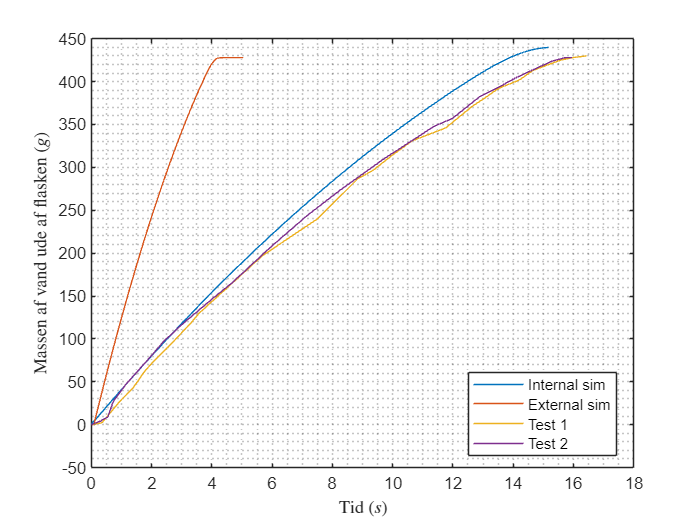

clear all
clf

% m_0 = 0.426287483 %kg

format longg
% Define the filename and sheetname
sheetname = 'Plot Data';

% Import data from Excel file
[numericData1, textData, rawData] = xlsread("GG Mass of Water 1.xlsx", sheetname);
time_internal_sim = numericData1(:,1);
mass_internal_sim = (numericData1(1,2) - numericData1(:,2)) * 1000;

[numericData1, textData, rawData] = xlsread("GG Mass of Water 1_external.xlsx", sheetname);
time_external_sim = numericData1(:,1);
mass_external_sim = (numericData1(1,2) - numericData1(:,2)) * 1000;


[numericData1, textData, rawData] = xlsread("Resultater fra eksperiment.xlsx");
test1_tid = numericData1(:,2);
test1_mass = numericData1(:,3);
test2_tid = numericData1(:,4);
test2_mass = numericData1(:,5);

plot(time_internal_sim,mass_internal_sim, DisplayName='Internal sim')
hold on
plot(time_external_sim,mass_external_sim, DisplayName='External sim')
plot(test1_tid,test1_mass, DisplayName='Test 1')
plot(test2_tid,test2_mass, DisplayName='Test 2')
% title('Massen af vand der kommet ud af flasken');
xlabel('Tid $(s)$',Interpreter='latex')
ylabel('Massen af vand ude af flasken $\left(g\right)$', Interpreter='latex')
grid("minor")
legend(Location="best")
hold off

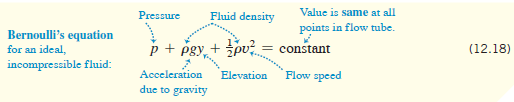

h1 = 0.26;
h2 = 0;
v1 = 0;
syms v2
rho = 997;
g = 9.82;



eq = rho * g * h1 + 1/2 * rho * v1^2 == rho * g * h2 + 1/2 * rho * v2^2

$$eq = \frac{5597702537547141}{2199023255552}=\frac{997\,{v_{2}}^{2}}{2}$$


v2_sol = solve(eq, v2)

$$v2\_sol = \left(\begin{array}{c} -\frac{3\,\sqrt{620101047770499953}}{1045430272}\\ \frac{3\,\sqrt{620101047770499953}}{1045430272} \end{array}\right)$$

vpa(v2_sol(2), 5)

$$ans = 2.2597$$